Lab 3 Part 1

clear
clc

Part 1

System 1:

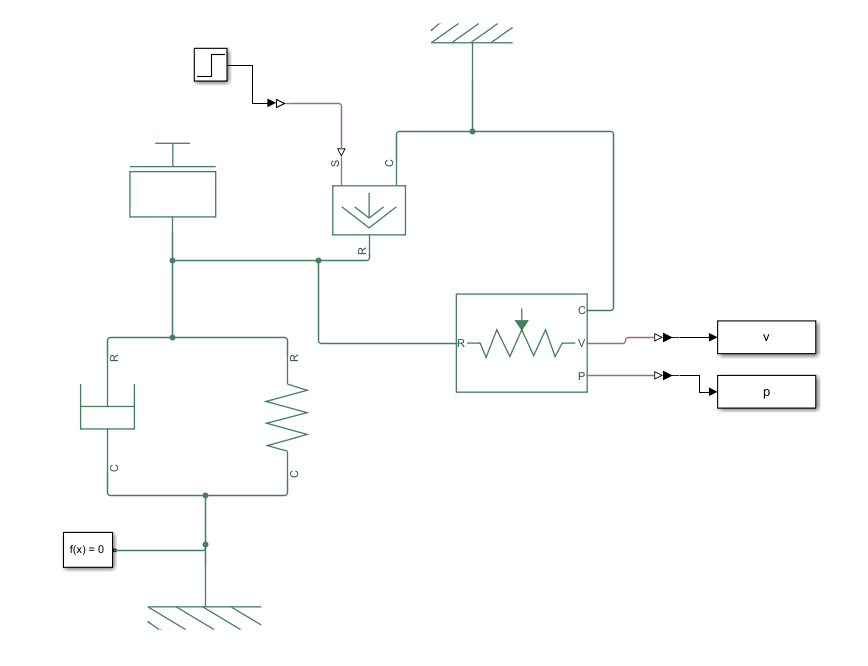

simscape model

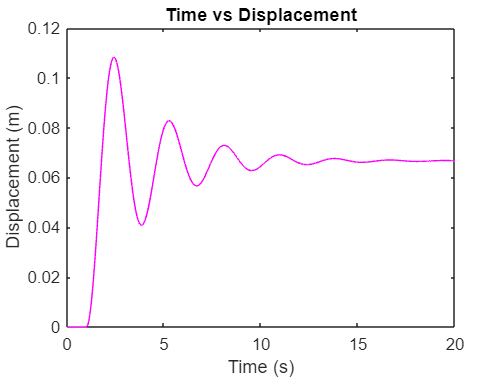

%open('Lab3_Part1.slx')
sim('Lab3_Part1.slx');
figure(1)
plot(tout,p,'m')
title("Time vs Displacement")
xlabel("Time (s)")
ylabel('Displacement (m)')

%This is a plot for velocity that is not required so i commented it out
% figure(2)
% plot(tout,v,'m')
% title("Time vs Velocity")
% xlabel("Time (s)")
% ylabel('Velocity (m/s)')

System 2:

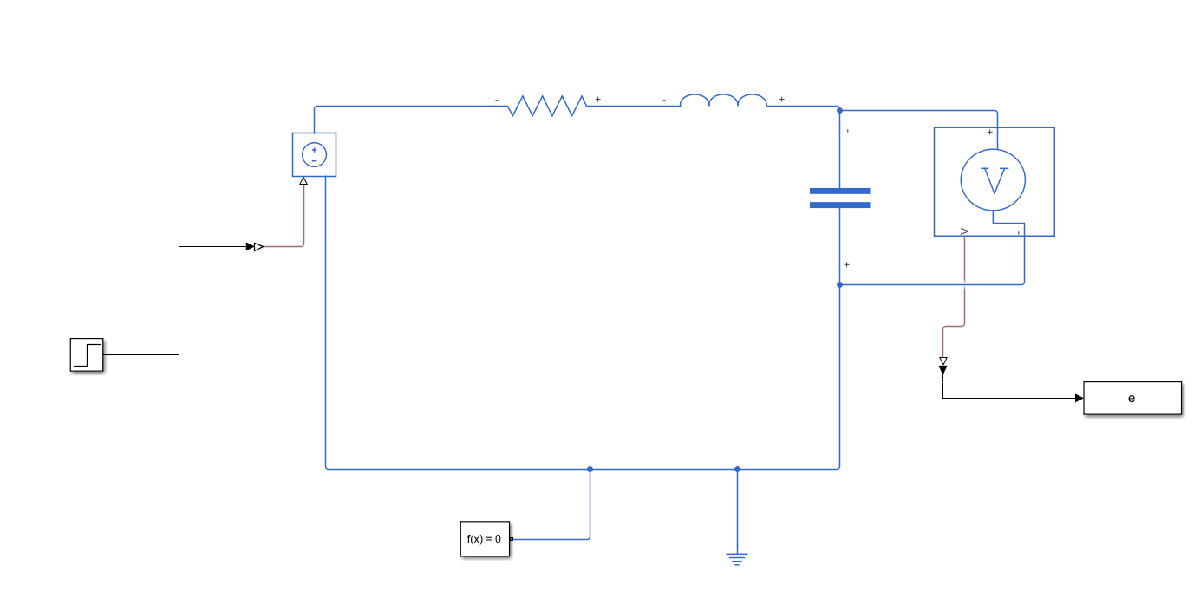

simcape model

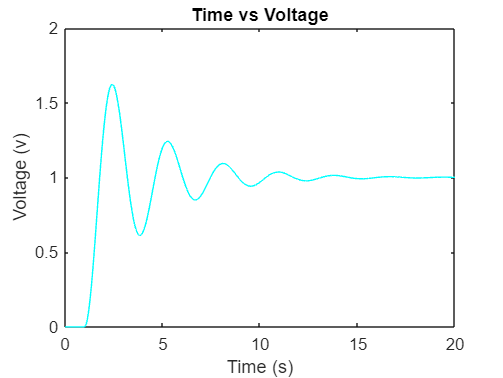

%open("lab3_part1_2.slx")
sim("lab3_part1_2.slx");
figure(2)
plot(tout,e,'c')
title("Time vs Voltage")
xlabel("Time (s)")
ylabel('Voltage (v)')

Part 2

System 1 Hand Derivations

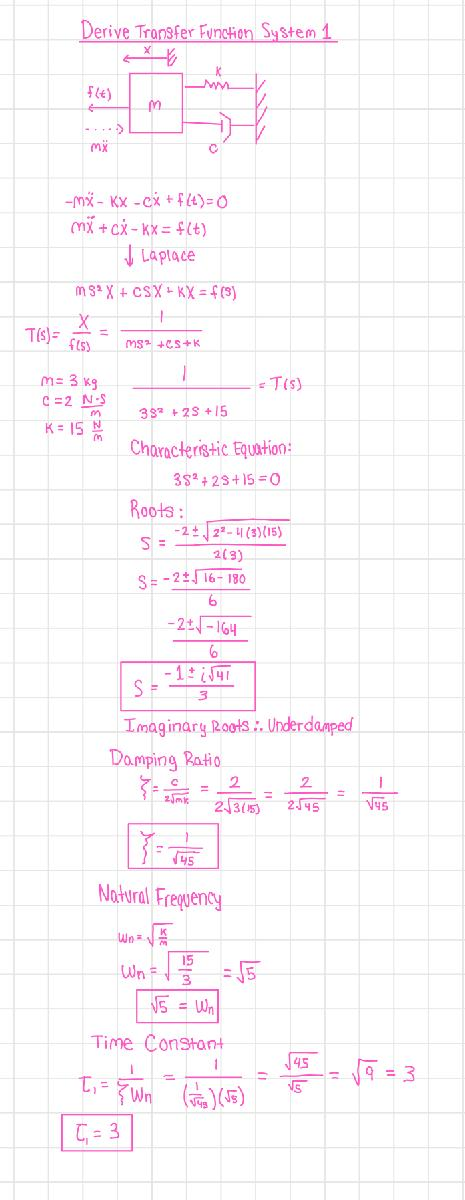

%Transfer function Check
sys1=tf([1],[3,2,15])

sys1 =
 
         1
  ----------------
  3 s^2 + 2 s + 15
 
Continuous-time transfer function.



[wn_1,zeta_1,s_1]=damp(sys1)

wn_1 =     2.2361
    2.2361


zeta_1 =     0.1491
    0.1491


s_1 =   -0.3333 + 2.2111i
  -0.3333 - 2.2111i


%wn_1 is natural frequency
%zeta_1 is damping ratio
%s_1 is the roots
t1=1/(wn_1(1)*zeta_1(1)) 

t1 = 3.0000

%t1 is the time constant calculated using the equation for underdamped
%systems


System 2

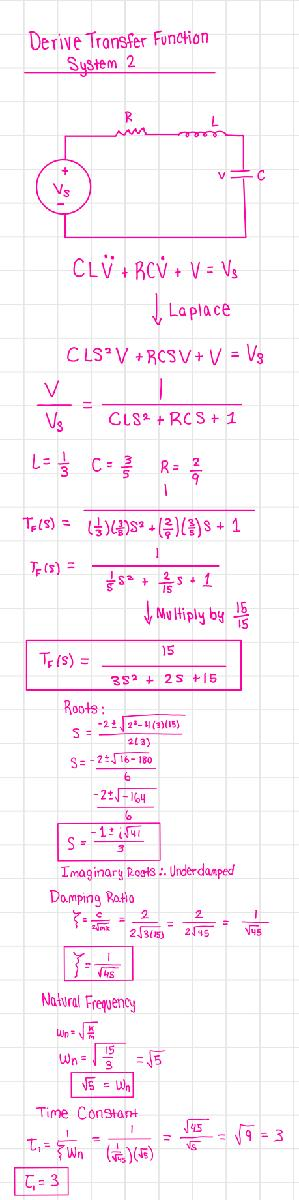

%Transfer Function Check
sys2=tf([15],[3,2,15])

sys2 =
 
         15
  ----------------
  3 s^2 + 2 s + 15
 
Continuous-time transfer function.



[wn_2,zeta_2,s_2]=damp(sys2)

wn_2 =     2.2361
    2.2361


zeta_2 =     0.1491
    0.1491


s_2 =   -0.3333 + 2.2111i
  -0.3333 - 2.2111i


%wn_2 is natural frequency
%zeta_2 is damping ratio
%s_2 is the roots
t2=1/(wn_2(1)*zeta_2(1)) 

t2 = 3.0000

%t2 is the time constant calculated using the equation for underdamped
%systems

History Details Hand Calculations

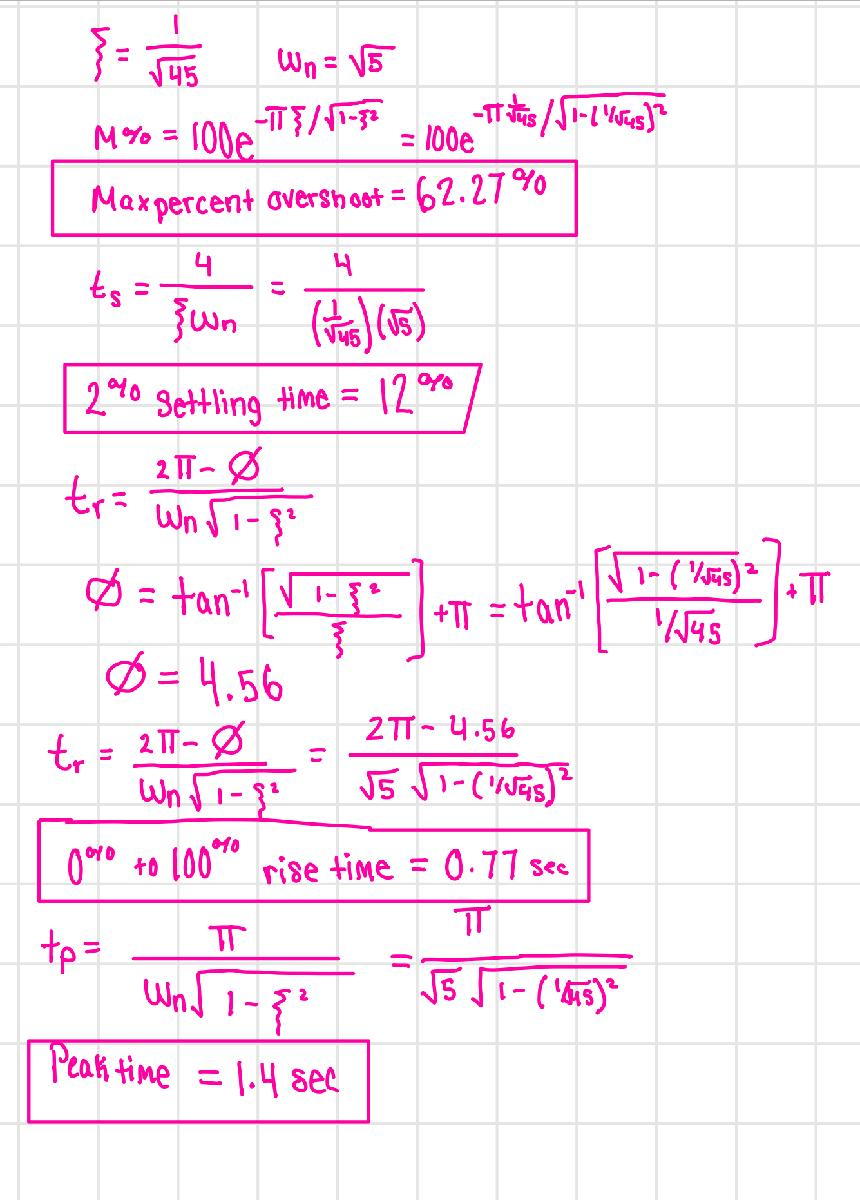

Matlab Comparison of history details

System_1_History=stepinfo(sys1)

System_1_History = struct with fields:
         RiseTime: 0.5255
    TransientTime: 11.5847
     SettlingTime: 11.5847
      SettlingMin: 0.0410
      SettlingMax: 0.1080
        Overshoot: 62.0326
       Undershoot: 0
             Peak: 0.1080
         PeakTime: 1.3816


System_2_History=stepinfo(sys2)

System_2_History = struct with fields:
         RiseTime: 0.5255
    TransientTime: 11.5847
     SettlingTime: 11.5847
      SettlingMin: 0.6156
      SettlingMax: 1.6203
        Overshoot: 62.0326
       Undershoot: 0
             Peak: 1.6203
         PeakTime: 1.3816
